clear
clc


Practice example from https://www.mathworks.com/help/matlab/ref/table.html#btw1wrc-3

% LastName = {'Sanchez';'Johnson';'Li';'Diaz';'Brown'};
% Age = [38;43;38;40;49];
% Smoker = logical([1;0;1;0;1]);
% % Smoker = logical( zeros( numel(Age),3) );
% Height = [71;69;64;67;64];
% Weight = [176;163;131;133;119];
% BloodPressure = [124 93; 109 77; 125 83; 117 75; 122 80];
% 
% T = table(LastName,Age,Smoker,Height,Weight,BloodPressure)
% f = uifigure;
% uit = uitable(f, 'data',T);
% uit.ColumnEditable = true;

Make our table of constraints

Metrics       = {'rf'; 'rg'; 'cct';...
    'duv'; 'sOpicDER'; 'mOpicDER';...
    'lOpicDER';'melOpicDER'; 'rOpicDER'};
UseTF    = logical( zeros(numel(Metrics),1 ) ); %default to no constraints

LessThanTF    = logical(zeros(numel(Metrics),1));
EqualToTF     = logical(ones(numel(Metrics),1)); %default
GreaterThanTF = logical(zeros(numel(Metrics),1) );

LessThanVal    = 1*inf*ones( numel(Metrics), 1);
EqualToVal     = [70; 70; 6500; 0; 1; 1; 1; 1; 1]; %default
GreaterThanVal = -1*inf*ones( numel(Metrics),1);

constraints_Table = table(Metrics, UseTF, LessThanTF, LessThanVal, EqualToTF, EqualToVal, GreaterThanTF,GreaterThanVal)

constraints_Table = 9×8 table
       Metrics        UseTF    LessThanTF    LessThanVal    EqualToTF    EqualToVal    GreaterThanTF    GreaterThanVal
    ______________    _____    __________    ___________    _________    __________    _____________    ______________

    {'rf'        }    false      false           Inf          true            70           false             -Inf     
    {'rg'        }    false      false           Inf          true            70           false             -Inf     
    {'cct'       }    false      false           Inf          true          6500           false             -Inf     
    {'duv'       }    false      false           Inf          true             0           false      

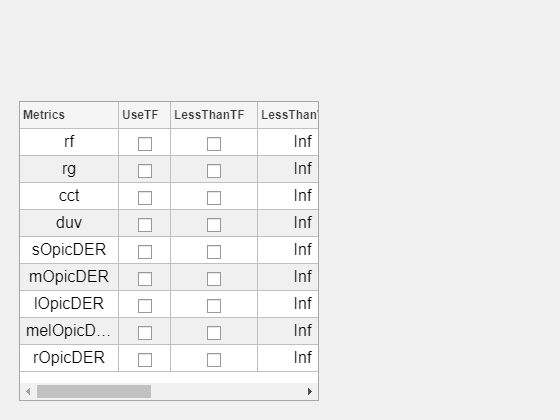

f = uifigure;
uit_constraints = uitable(f, 'data', constraints_Table); 
uit_constraints.ColumnEditable = true;
uit_constraints.ColumnWidth = 'fit'; %narrower columns
uit_constraints.FontSize = 16;

s = uistyle('HorizontalAlignment','center');
% addStyle(uit_constraints,s,'column',2:width(uit_constraints.Data));
addStyle(uit_constraints,s);


% uit_constraints.DisplayDataChangedFcn = @updateConstraints;

% function 
% Equality = 

